## ROBOTICS PROJECT

clear all
close all

Definizione degli agenti, posizioni casuali e orientamenti casuali  (3D)

settare la comunicazione con handshaking (common network)

*definizione: fatto*

*manca settare la rete *

% initialize UGV struct
ugv.xw = 0;  ugv.yw = 0; ugv.hw = -pi/4;    % robot position and orientation wrt world frame
ugv.xr = 0;  ugv.yr = 0; ugv.hr = 0;    % robot position and orientation wrt its frame

% define position of visual features of UGV
ugv.P1 = [0.2; 0.15; 0.2];      %[m]
ugv.P2 = [0.2; -0.15; 0.2];     %[m]
ugv.P3 = [-0.2; -0.15; 0.2];    %[m]
ugv.P4 = [-0.2; 0.15; 0.2];     %[m]

% !!! pose wrt its frame is needed only to have the right arrays and matrices dimension

% initialize AUV struct 


formation.alt = 3;                  % formation altitude
formation.r = 3;                    % formation radius
formation.offset = 0.5;             % altitude offset to perform large movement 

auv.n  = 7;                             % number of auvs
    
auv.id =    zeros(auv.n,1);             % auv id 
auv.xw =    rand(auv.n,1)*6-3 ;         % coords in world frame
auv.yw =    rand(auv.n,1)*6-3 ;
auv.zw =    0.1*ones(auv.n,1);

auv.rollw  =  zeros(auv.n,1);           % roll angle in world frame
auv.pitchw =  zeros(auv.n,1);           % pitch angle in world frame
auv.yaww   =  rand(auv.n,1)*2*pi;       % yaw angle in world frame

auv.xr = auv.xw - ugv.xw;               % coords in robot frame (UGV)
auv.yr = auv.yw - ugv.yw;  
auv.zr = auv.zw; 

auv.rollr = auv.rollw ;                 % we suppose initial roll and pitch
auv.pitchr = auv.pitchw;                % angles will always be zero, only
auv.yawr = auv.yaww - ugv.hw;           % yaw angle may be different

% camera parameters:

cam.fov.x = 1.2572;                                 % vertical  fov [rad]
cam.fov.y = 1.4408;                                 % orizontal fov [rad]
cam.f = 3.6*10^-3;                                  % focal length  [m]
cam.ImagePlaneSize = [6.32*10^-3  4.74*10^-3];      % Y x X         [m  m]
cam.PixelDensity = [4000  3000];                    % Y x X - adimensional


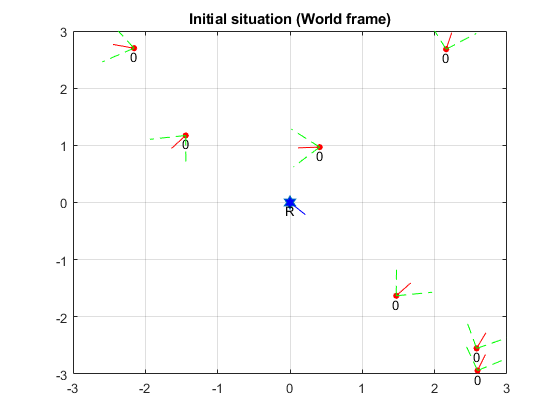

%% visualize the initial situation

% generate labels for plot
labels = generateLabels(auv);

% plot the situation
figure(1);
plotFlock(auv,ugv,cam,labels);
axis([-3 3 -3 3]);
grid on;

title('Initial situation (World frame)');

Definizione traiettoria ugv, e generiamo la traiettoria controllata da simulink (2D)

*fatto (volendo migliorare il controllore di simulink)*

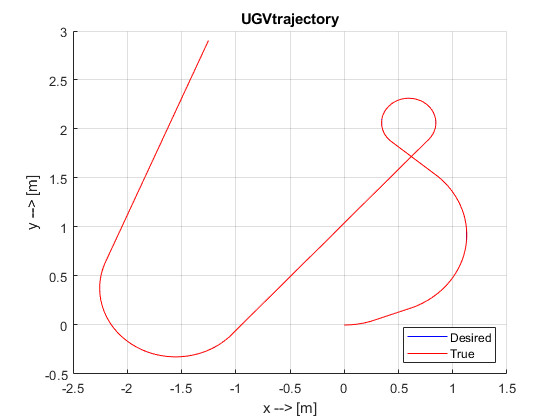

% Run UGV_init (./trajectories_and_controllers) for more details!

% Initialize the Unicycle model
run initializeUnicycleModel.m

% Generate the trajectory
run UGV_trajectory_generation.m

% Set the controller parameters
run UGV_ctrl_params.m

%% simulate
open_system('UGV_21a.slx');
UGVRealPose = sim('UGV_21a.slx', 'ReturnWorkspaceOutputs', 'on');

figure(2);
hold on
plot(ugv.trajectory.signals.values(:,1), ugv.trajectory.signals.values(:,2), 'b');
%axis([-3 2 -0.5 3]);
grid on;
title('UGVtrajectory');
legendInfo=string(zeros(2,1));
legendInfo(1, 1) = sprintf('Desired');

% plot real trajectory of the ugv
plot(UGVRealPose.Pose.signals.values(:,1), UGVRealPose.Pose.signals.values(:,2), 'r');
legendInfo(2, 1) = sprintf('True');

legend(legendInfo(:,:),'Location','SouthEast');
xlabel('x --> [m]')
ylabel('y --> [m]')

definizione decollo degli uav e generazione trajectory in simulink (3D)

*fatto*  

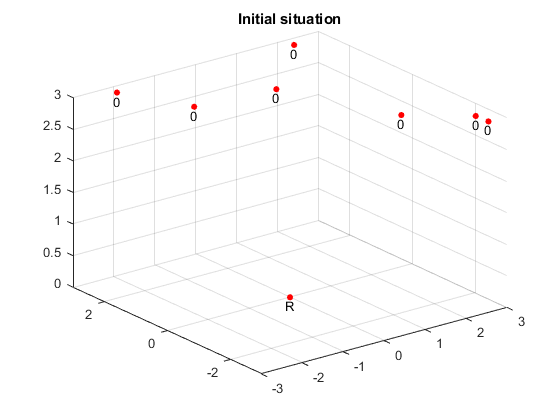

% take off
auv.zr = formation.alt * ones(auv.n,1);
auv.zw = auv.zr;

%% we create a UAVSimulationVECTOR as a vector of signals that holds the
% wanted trajectory that each uav must follow. This trajectory is defined
% wrt the initial frame of each UAV
UAVSimulation.signals.values = zeros(T/Ts, 4);  % [x, y, z, yaw]
UAVSimulation.time = zeros(T/Ts,1);
%for i=1:1:size(UAVSimulation.time,1)
%    UAVSimulation.time(i)= Ts*i;
%end

UAVSimulationVECTOR = [UAVSimulation UAVSimulation];

for auv_idx=3:auv.n
    UAVSimulationVECTOR = [UAVSimulationVECTOR UAVSimulation];
end

% simulate take-off in 1.5 second
Pose=[0 0 0 0];     % [x, y, z, yaw] initial
NextPose=[0 0 auv.zr(1) 0]; % [x, y, z, yaw] after take-off
    
Trajectory = computeUAVTrajectory(Pose,NextPose,1.5);

for auv_idx=1:auv.n
    UAVSimulationVECTOR(auv_idx).signals.values(1:size(Trajectory,1),:) = Trajectory(:,1:4);
    for i=1:1:size(Trajectory,1)
        UAVSimulationVECTOR(auv_idx).time(i)= Ts*i;
    end
end

%% visualize the situation after take-off (simulated)
figure(3);
plot3([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],'or','MarkerSize',4,'MarkerFaceColor','r')
text([auv.xr; ugv.xr],[auv.yr; ugv.yr],[auv.zr; 0],labels,'VerticalAlignment','top','HorizontalAlignment','center')
axis([-3 3 -3 3])   
title('Initial situation');
grid on;

I droni cercano di vedere l'ugv con la telecamera con movimenti e rotazioni casuali (3D)

dal momento in cui un drone vede l'ugv, lo comunica, ed entra nella rete di formazione (formation network)

*da aggiungere: *

*-la semplice rotazione basta per trovare il robot prima o poi, ma se il drone è stato spawnato troppo vicino al robot, non lo vedrà mai, perchè il robot si trova esattamente sotto di lui.*

*Si potrebbe aggiungere che se dopo aver fatto il giro completo su se stesso, il drone ancora non vede il robot, indietreggia di tot m, e ricomincia a girare.*

*- lo schema e il calcolo del grafo con le varie matrici ogni volta che la formazione (quindi la rete) cambia perchè si è aggiunto qualcuno.*

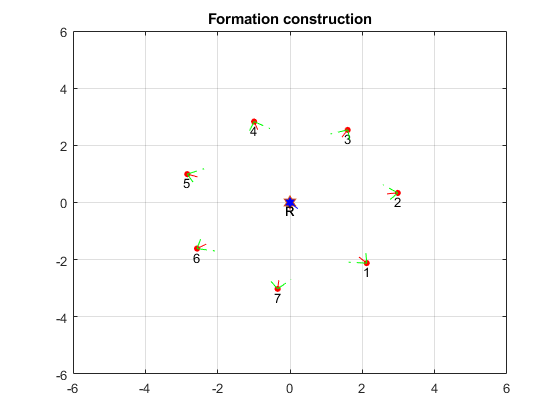

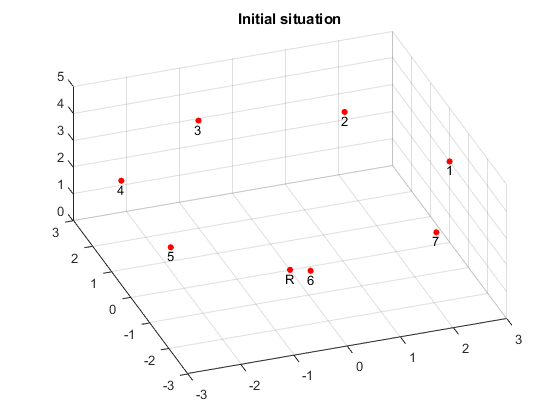

% create two auv structures: out_auv struct for the auvs that don't see the
% ugv yet and form_auv for the auvs that see the ugv and so can go in formation.
out_auv = auv;
form_auv.n = 0;


update_formation = false;
form_complete = false;

max_it = 100;
it = 1;


% auv search the robot
while(form_auv.n~=auv.n || form_complete == false)
    
    labels_out = generateLabels(out_auv);
    labels_form = generateLabels(form_auv);
    
    
    
%     ugv.hw = ugv.hw +0.01;    
%     ugv.xw = ugv.trajectory.signals.values(it*100,1);
%     ugv.yw = ugv.trajectory.signals.values(it*100,2);
%     ugv.hw = ugv.trajectory.signals.values(it*100,3);
    
    figure(4);
    plotFlock(out_auv,ugv,cam,labels_out);
    hold on;
    plotFlock(form_auv,ugv,cam,labels_form);
    hold off;
    lim = formation.r  * 2;
    axis([-lim lim -lim lim ]);
    grid on;
    title("Formation construction")
    it=it+1;
 
    pause(.01)
    
    %% --------------- AUVS NOT IN FORMATION
    % check if auvs not in formation see the robot
    rem = [];
    out_auv = glob2rel(out_auv, ugv);
    for i = 1 : out_auv.n
        
        auv_pos = [out_auv.xr(i) out_auv.yr(i) out_auv.zr(i)];
        auv_rpy = [out_auv.rollr(i) out_auv.pitchr(i) out_auv.yaww(i)];
        
        [is_inside1,x1,y1] = computeCameraImage(auv_pos,auv_rpy,ugv.P1.');
        [is_inside2,x2,y2] = computeCameraImage(auv_pos,auv_rpy,ugv.P2.');
        [is_inside3,x3,y3] = computeCameraImage(auv_pos,auv_rpy,ugv.P3.');
        [is_inside4,x4,y4] = computeCameraImage(auv_pos,auv_rpy,ugv.P4.');
        
        

        if(is_inside1 && is_inside2 && is_inside3 && is_inside4)    
         
            
            [droneLocation,droneOrientation] = PoseReconstruction([x1 y1; x2 y2; x3 y3; x4 y4]);
            
            theta = atan2(droneOrientation(3,2),droneOrientation(3,3));
            
            
            % add the auv to the formation  
            out_auv.id(i) = form_auv.n+1;
            form_auv = addToFormation(form_auv,out_auv,i);
            rem(end+1) = i;    
            update_formation = true;
            %it = 1;
        else
            out_auv.yaww(i) = out_auv.yaww(i)+0.2;
        end
    end
    out_auv = removeAuvFrom(out_auv, rem);

        
    %% --------------- AUVS IN FORMATION
    if(form_auv.n > 1) 
        form_auv = consensusPolarFormation(form_auv,ugv,formation,update_formation,0.1);
        %form_auv.yawr = pi;
        update_formation = false;
%         if(max(form_auv.travel_dist) < 0.001 && max(form_auv.th_err) < 0.05)
%             form_complete = true;
%         else
%             form_complete = false;
%         end
    end
    
    if(it == max_it)
        break;
    end
end


if(form_auv.n==auv.n && form_complete == true)
    fprintf('Every auv is in formation after %d iterations',it);
elseif(form_auv.n~=auv.n && form_complete == true)
    fprintf('Formation complete with some auv missing after %d iterations',it);
elseif(form_auv.n==auv.n && form_complete == false)
    fprintf('Every auvs is pointing to the robot but the formation is not ready %d iterations',it);
else
    fprintf('Fail after max iterations, try to increase max_it')    
end

Every auvs is pointing to the robot but the formation is not ready 100 iterations

consenso della formazione offline  (2D) 

*fatto, da modificare per avere meno iterazioni a discapito di eventuali sovrapposizioni, che non sono più un problema   GIOELE*

for i = 1 : form_auv.n
        auv_pos = [form_auv.xr(i) form_auv.yr(i) form_auv.zr(i)];
        auv_rpy = [form_auv.rollr(i) form_auv.pitchr(i) form_auv.yawr(i)]; 
        
        ugv.R = [cos(ugv.hw) -sin(ugv.hw) 0;
                 sin(ugv.hw)  cos(ugv.hw) 0;
                 0            0           1];
        
        [is_inside1,x1,y1] = computeCameraImage(auv_pos,auv_rpy,(ugv.R*ugv.P1).');
        [is_inside2,x2,y2] = computeCameraImage(auv_pos,auv_rpy,(ugv.R*ugv.P2).');
        [is_inside3,x3,y3] = computeCameraImage(auv_pos,auv_rpy,(ugv.R*ugv.P3).');
        [is_inside4,x4,y4] = computeCameraImage(auv_pos,auv_rpy,(ugv.R*ugv.P4).');
        
       
            i
            
            [droneLocation,droneOrientation] = PoseReconstruction([x1 y1; x2 y2; x3 y3; x4 y4])
            
            theta = atan2(droneOrientation(2,1),droneOrientation(1,1))
end

i = 1

droneLocation =     2.1683    2.0977    2.9728


droneOrientation =    -0.7139    0.7002    0.0105
   -0.7002   -0.7139    0.0002
    0.0076   -0.0072    0.9999


theta = -2.3659

i = 2

droneLocation =    -0.2589    2.9927    2.9804


droneOrientation =     0.1035    0.9945    0.0187
   -0.9946    0.1034    0.0062
    0.0042   -0.0192    0.9998


theta = -1.4671

i = 3

droneLocation =    -2.4964    1.6034    3.0209


droneOrientation =     0.8415    0.5402    0.0079
   -0.5402    0.8415   -0.0052
   -0.0094    0.0001    1.0000


theta = -0.5707

i = 4

droneLocation =    -2.8529   -0.9773    2.9875


droneOrientation =     0.9450   -0.3269   -0.0054
    0.3269    0.9450    0.0011
    0.0047   -0.0028    1.0000


theta = 0.3331

i = 5

droneLocation =    -0.9930   -2.8347    3.0575


droneOrientation =     0.3316   -0.9434    0.0048
    0.9434    0.3316    0.0099
   -0.0109    0.0012    0.9999


theta = 1.2328

i = 6

droneLocation =     1.7083   -2.5077    2.9896


droneOrientation =    -0.5478   -0.8364    0.0178
    0.8366   -0.5477    0.0094
    0.0019    0.0200    0.9998


theta = 2.1505

i = 7

droneLocation =     3.0043   -0.2466    3.0388


droneOrientation =    -0.9948   -0.1020   -0.0088
    0.1017   -0.9945    0.0229
   -0.0111    0.0219    0.9997


theta = 3.0397

una volta che le posizioni della formazione sono ben definite (con un threshold sulla convergenza) 

si va in formazione (3D) con la traiettoria calcolata (traj relativa tra loro pos e ugv)

*calcolo traiettoria e generarla con simulink*

#### ciclo: (ogni 0.5 s consenso sul movimento UGV, e per ora verificare quanto si rovina la formazione, poi, aggiungere consenso formazione ogni tot)

una volta in formazione UGV si muove, 

lettura con la camera -> imageplane

imageplane -> pose recovery (misura sporca di rototransl)

*ricavare tutte le rototranslazioni e usare pose recovery che è già fatta*

consensus sulla posizione del ugv k-1 (consensus average sulla posizione del ugv dopo che si è mosso)  (2D)

*da fare *

calcolo traiettoria droni per mantenere CoM, con controllo yaw per mantere ugv all'interno dell'image plane

attuazione della traiettoria se fattibile con simulik, altrimenti, semplicemente in 2D qui

*da fare*